# Descriptors

## Aparellar figures

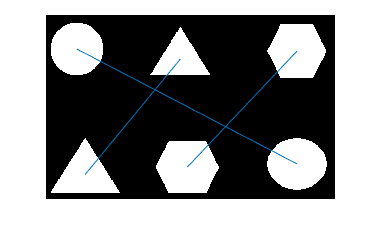

BW = rgb2gray(imread("figures.png")) < 200;
imshow(BW);
BWU = BW;
BWU(end/2:end,:) = 0;
BWD = BW;
BWD(1:end/2,:) = 0;
%imshow(BWU);
%imshow(BWD);
CCU = bwconncomp(BWU);
CCD = bwconncomp(BWD);
propsU = regionprops('table', CCU, 'Centroid','BoundingBox', 'Circularity');
propsD = regionprops('table', CCD, 'Centroid','BoundingBox', 'Circularity');
NumObj = CCU.NumObjects;

% emparellar
FU = [propsU.Circularity];
FD = [propsD.Circularity];

Assig = dsearchn(FD,FU);

% dibuixar emparallement
hold on
for i=1:NumObj
    line([propsU.Centroid(i,1) propsD.Centroid(Assig(i),1)],[propsU.Centroid(i,2) propsD.Centroid(Assig(i),2)]);
end
hold off

## Aparellar abecedari

BW = rgb2gray(imread("Abecedari.png")) < 200;
imshow(BW);
BWU = BW;
BWU(end/2:end,:) = 0;

BWD = BW;
BWD(1:end/2,:) = 0;

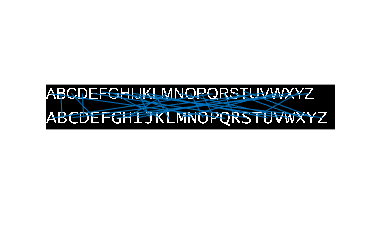

%imshow(BWU);
%imshow(BWD);
CCU = bwconncomp(BWU);
CCD = bwconncomp(BWD);
propsU = regionprops('table', CCU, 'Centroid','BoundingBox', 'Circularity','Solidity','EulerNumber', 'Orientation');
propsD = regionprops('table', CCD, 'Centroid','BoundingBox', 'Circularity', 'Solidity','EulerNumber', 'Orientation');
NumObj = CCU.NumObjects;

% emparellar
FU = [propsU.Circularity, propsU.Solidity, propsU.EulerNumber, propsU.Orientation];
FD = [propsD.Circularity, propsD.Solidity, propsD.EulerNumber, propsD.Orientation];

FU(:,1) = FU(:,1)./max(FU(:,1));
FD(:,1) = FD(:,1)./max(FD(:,1));
FU(:,2) = FU(:,2)./max(FU(:,2));
FD(:,2) = FD(:,2)./max(FD(:,2));
FU(:,3) = FU(:,3)./max(FU(:,3));
FD(:,3) = FD(:,3)./max(FD(:,3));
FU(:,4) = FU(:,4)./max(FU(:,4));
FD(:,4) = FD(:,4)./max(FD(:,4));

A = zeros(NumObj,NumObj);
for i = 1:NumObj
    for j = 1:NumObj
        A(j,i) = norm(FU(i,:) - FD(j,:));
    end
end

for k = 1:NumObj
    [Amins, idx] = min(A);
    [Amin, Ai] = min(Amins);
    Aj = idx(Ai);
    Assig(Ai) = Aj;
    A(Aj,:) = Inf;
    A(:,Ai) = Inf;
end

% dibuixar emparallement
hold on
for i=1:NumObj
    line([propsU.Centroid(i,1) propsD.Centroid(Assig(i),1)],[propsU.Centroid(i,2) propsD.Centroid(Assig(i),2)]);
end
hold off

## Descriptors de Fourier

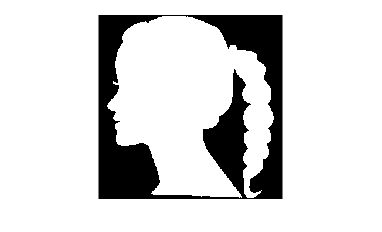

im = imread('head.png');
im = imresize(im,0.5);
imshow(im);

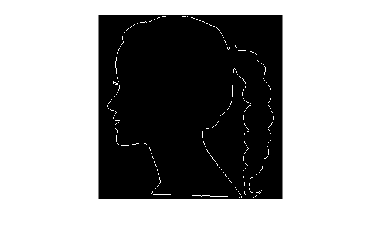

cont = xor(im, imerode(im, strel('disk', 1)));
imshow(cont);

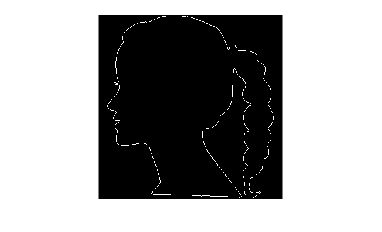

[fila, col] = find(cont,1);
B = bwtraceboundary(cont, [fila,col], 'E');

mig = mean(B);
Bc = B - mig;
s = Bc(:,1) + Bc(:,2) * 1i;
%Transformada fourier
z = fft(s);
% Transformada inversa de fourier
ss = ifft(z);
aux = zeros(size(im));
files = round(real(ss) + mig(1));
cols = round(imag(ss) + mig(2));
aux(sub2ind(size(aux), files, cols)) = 1;
imshow(aux);

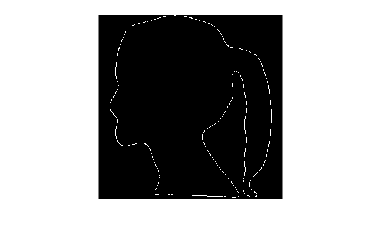


% Agafem només 30 components
N = 30;
zz = z;
zz(N+1:end-N) = 0;
ss30 = ifft(zz);
aux30 = zeros(size(im));
files = round(real(ss30) + mig(1));
cols = round(imag(ss30) + mig(2));
aux30(sub2ind(size(aux), files, cols)) = 1;
imshow(aux30);

## Descriptors de Fourier de la lletra Z

rect = propsU.BoundingBox(26,:);
im = BWU(rect(2)-1:rect(2)+rect(4),rect(1)-1:rect(1)+rect(3));

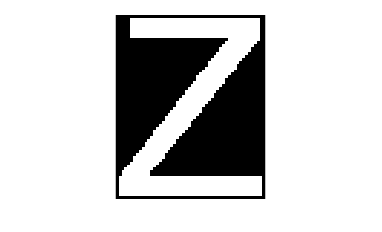

imshow(im);

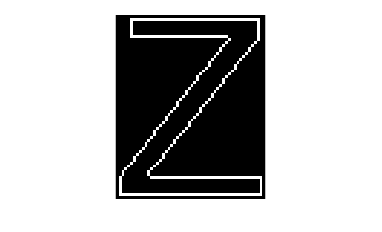

cont = xor(im, imerode(im, strel('disk', 1)));
imshow(cont);

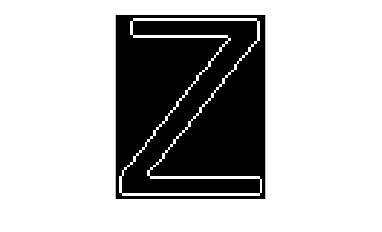

[fila, col] = find(cont,1);
B = bwtraceboundary(cont, [fila,col], 'E');

mig = mean(B);
Bc = B - mig;
s = Bc(:,1) + Bc(:,2) * 1i;
%Transformada fourier
z = fft(s);
% Transformada inversa de fourier
ss = ifft(z);
aux = zeros(size(im));
files = round(real(ss) + mig(1));
cols = round(imag(ss) + mig(2));
aux(sub2ind(size(aux), files, cols)) = 1;
imshow(aux);

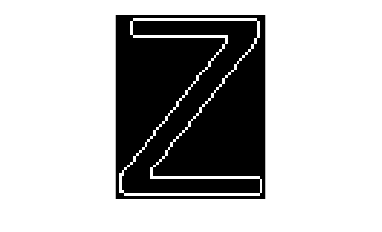


% Agafem només 30 components
N = 30;
zz = z;
zz(N+1:end-N) = 0;
ss30 = ifft(zz);
aux30 = zeros(size(im));
files = round(real(ss30) + mig(1));
cols = round(imag(ss30) + mig(2));
aux30(sub2ind(size(aux), files, cols)) = 1;
imshow(aux30);


desc = abs(zz(1:N));